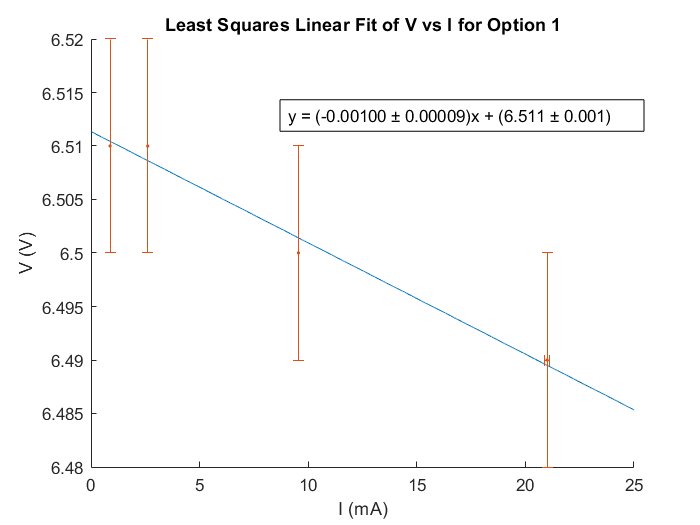

%example of a linear least squares fit of specific experimental data (voltage vs
%current)

x1 = [21.0,9.55,2.61,0.877]';
y1 = [6.49,6.50,6.51,6.51]';
xerr1 = [0.1,0.01,0.01,0.001]'; %reading error
yerr1 = [0.01,0.01,0.01,0.01]'; %error from multimeter (reading error)
tbl1 = table(x1,y1,xerr1,yerr1,'VariableNames',{'X','Y','XERR','YERR'});
lm1 = fitlm(tbl1,'Y ~ X');
hold on;
%p = plot(lm,'Marker','.')
results1 = table2array(lm1.Coefficients);
range = 0:0.001:25;
expected1 = results1(2,1)*range+results1(1,1);
plot(range,results1(2,1)*range+results1(1,1));
title("Least Squares Linear Fit of V vs I for Option 1");
xlabel("I (mA)");
ylabel("V (V)");
errorbar(x1,y1,yerr1,yerr1,xerr1,xerr1,'.')
annotation("textbox",[0.4 0.75 0.52 0.06],'String',"y = (-0.00100 ± 0.00009)x + (6.511 ± 0.001)")
hold off;

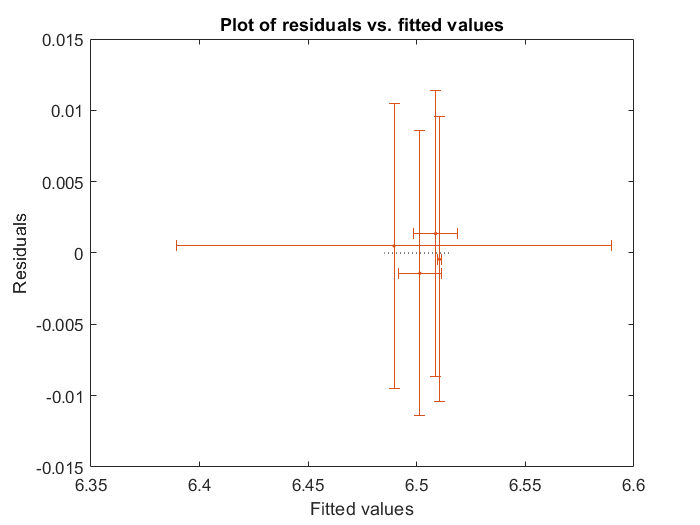


plotResiduals(lm1,'fitted','Marker','.')
hold on;
errorbar([6.489506527312579,6.501417362312156,6.508636680643779,6.510439429731488],[0.000493472687421,-0.001417362312156,0.001363319356221,-0.000439429731488],yerr1,yerr1,xerr1,xerr1,'.')
%chi squared is 1, reduced is 0.5
hold off;

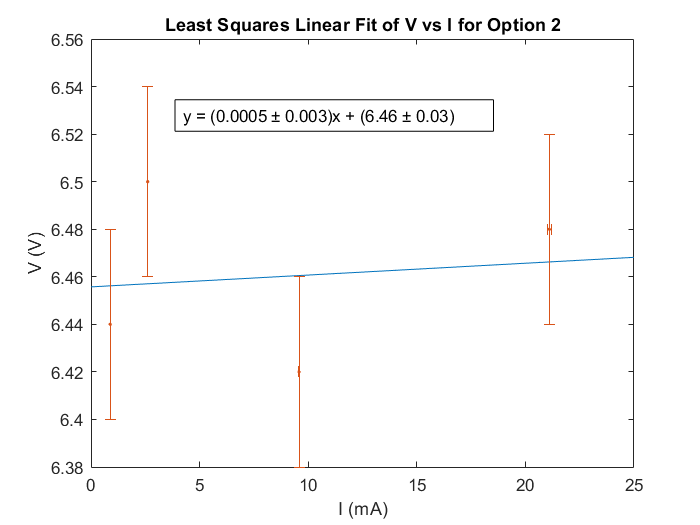


x2 = [21.1,9.58,2.61,0.881]';
y2 = [6.48,6.42,6.50,6.44]';
xerr2 = [0.1,0.01,0.01,0.001]'; %reading error
yerr2 = [0.04,0.04,0.04,0.04]'; %error from y variance (statistical)
tbl2 = table(x2,y2,xerr2,yerr2,'VariableNames',{'X','Y','XERR','YERR'});
lm2 = fitlm(tbl2,'Y ~ X');
%p = plot(lm,'Marker','.')
results2 = table2array(lm2.Coefficients);
range = 0:0.001:25;
expected2 = results2(2,1)*range+results2(1,1);
plot(range,results2(2,1)*range+results2(1,1));
title("Least Squares Linear Fit of V vs I for Option 2");
xlabel("I (mA)");
ylabel("V (V)");
hold on;
errorbar(x2,y2,yerr2,yerr2,xerr2,xerr2,'.')
annotation("textbox",[0.25 0.75 0.455 0.06],'String',"y = (0.0005 ± 0.003)x + (6.46 ± 0.03)")
hold off;

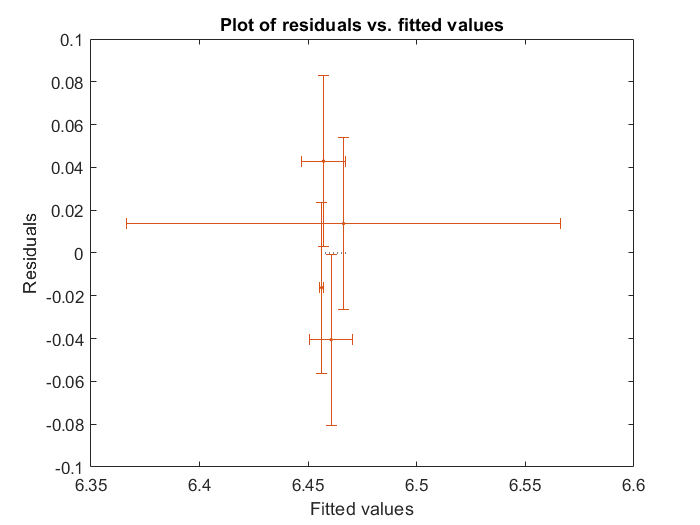

plotResiduals(lm2,'fitted','Marker','.')
hold on;
errorbar([6.466241341193103,6.460515545294754,6.457051239963895,6.456191873548248],[0.013758658806897,-0.040515545294754,0.042948760036105,-0.016191873548248],yerr2,yerr2,xerr2,xerr2,'.')
hold off;

%chi squared is 0.99 repeating 9 reduced is 0.499 repeating 9